# Eigen-Decomposition & Singular Value Decomposition

## Fix matrix

clc; clear; close all;
addpath('../data')

matrix_size = 200;
sparse_ratio = 0.7;

X = normrnd(0, 1, matrix_size, matrix_size);
X = X+X'; % symmetrization
tmp = quantile(abs(X(:)), sparse_ratio);
X(abs(X)<tmp) = 0.0;
disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X(1:5, 1:5))

         0         0         0         0         0
         0         0         0   -2.4188    1.8939
         0         0         0         0   -4.0048
         0   -2.4188         0    2.7799   -2.5592
         0    1.8939   -4.0048   -2.5592         0



## Eigen-decomposition

[U, S] = eig(X);
X_approx = full(U*S*U');

disp(['The Frobenius norm of two matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm of two matrix is 1.2335e-13.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

    0.0000   -0.0000    0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -2.4188    1.8939
    0.0000   -0.0000    0.0000   -0.0000   -4.0048
    0.0000   -2.4188   -0.0000    2.7799   -2.5592
   -0.0000    1.8939   -4.0048   -2.5592   -0.0000



## Sparse matrix

num_largest_ev = 7;
X_sparse = sparse(X);
[U, S] = eigs(X_sparse, num_largest_ev);
X_approx = full(U*S*U');

disp(['The Frobenius norm from approximation matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from approximation matrix is 32.1109.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

    0.5042    0.2203    0.2354    0.7073   -0.3591
    0.2203    0.3505   -0.5744   -0.2657    0.3043
    0.2354   -0.5744   -0.0797    0.7029   -0.8186
    0.7073   -0.2657    0.7029    0.0991   -0.4981
   -0.3591    0.3043   -0.8186   -0.4981    0.6718



## Singular value decomposition (SVD)

num_largest_ev = 7;
X_sparse = sparse(X);
[U, S, V] = svds(X_sparse, num_largest_ev);

X_approx = full(U*S*V');

disp(['The Frobenius norm from SVD matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from SVD matrix is 32.1109.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

    0.5042    0.2203    0.2354    0.7073   -0.3591
    0.2203    0.3505   -0.5744   -0.2657    0.3043
    0.2354   -0.5744   -0.0797    0.7029   -0.8186
    0.7073   -0.2657    0.7029    0.0991   -0.4981
   -0.3591    0.3043   -0.8186   -0.4981    0.6718



## Application of svd

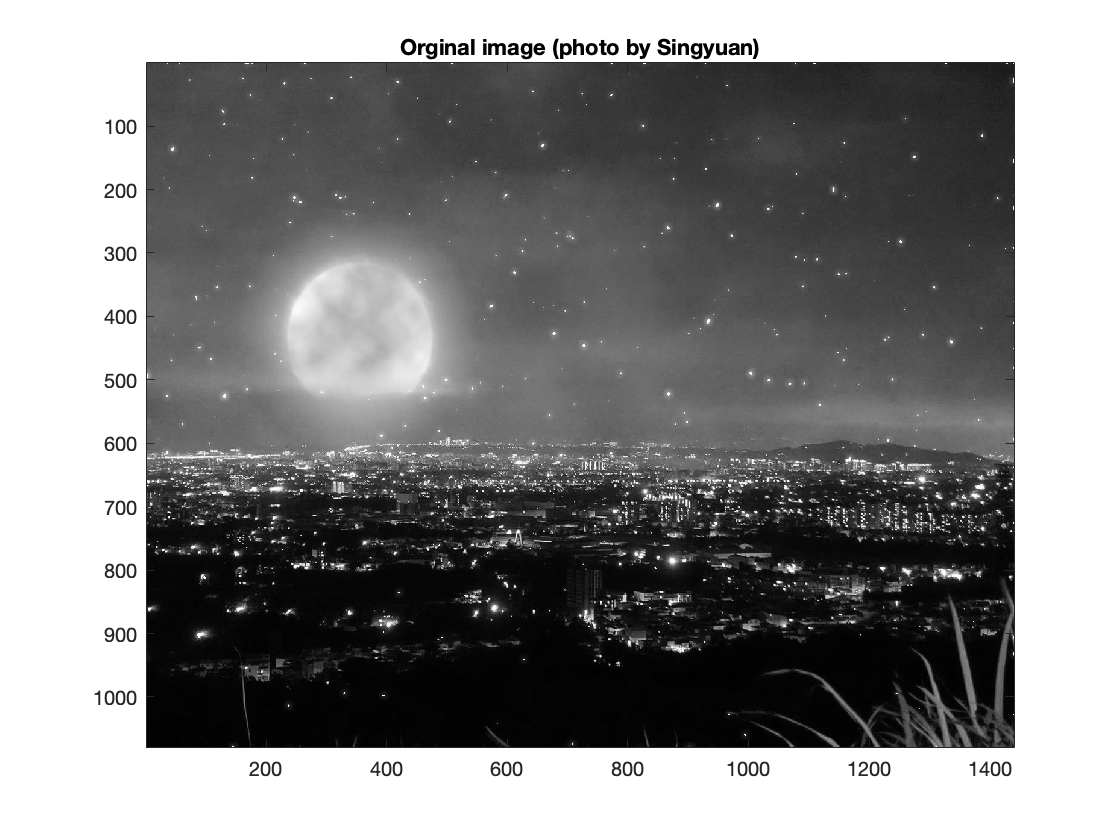

% X = imread('mountain.jpg');
% imshow(X)
% X = double(rgb2gray(X));
% X = X/255.0;
load('mountain_gray.mat')
mountain_gray;
figure
imagesc(mountain_gray);
colormap(gray);
title('Orginal image (photo by Singyuan)')

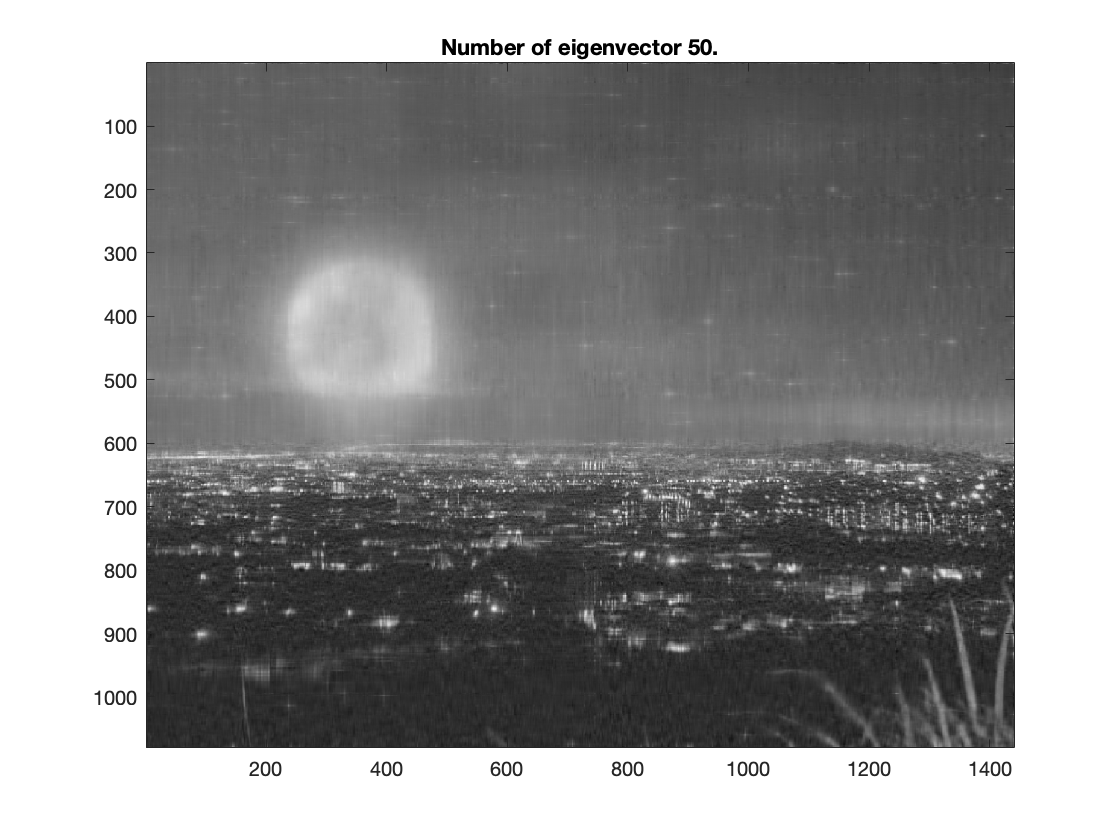


[U, S, V] = svd(mountain_gray);
figure
for i = 5:5:50
    imagesc(U(:, 1:i)*S(1:i, 1:i)*V(:, 1:i)');
    colormap(gray);
    title(['Number of eigenvector ', num2str(i), '.'])
    pause(0.5)
    drawnow
end